# Thực hiện trò chơi Chaos

[Menu menu chính](matlab:open('MainMenu.mlx'))

Sử dụng các điều khiển phân nhánh và vòng lặp từ[Cành](matlab:open('./Branches.mlx'))Và[Vòng lặp](matlab:open('./Loops.mlx')), kịch bản này sẽ hướng dẫn bạn xây dựng việc triển khai trò chơi Chaos từ xương trần đến khả năng tạo ra các thiết kế phức tạp tự động.

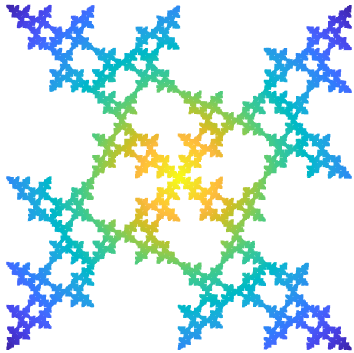         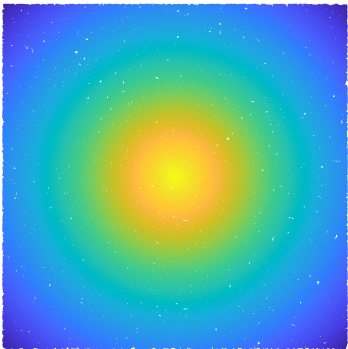         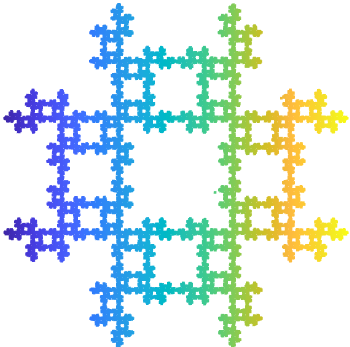

Dự án này sẽ tăng sự quen thuộc của bạn với các chi nhánh và vòng lặp trong bối cảnh mà tiện ích của chúng là chìa khóa để quan sát các kết quả mong muốn.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN**Xem**tab của công cụ MATLAB, trong**Xem**Phần, chọn**Đầu ra nội tuyến**. Thay phiên, chọn**Đầu ra nội tuyến**Sử dụng biểu tượng Ở phía trên bên phải của ngăn biên tập viên trực tiếp.

Tương tác với tập lệnh trực tiếp này sẽ xây dựng một số quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau, nhưng một số quen thuộc với môi trường biên tập trực tiếp đã được giới thiệu trong[Giới thiệu.MLX](matlab:open('./Introduction.mlx')). Một bản tóm tắt ngắn gọn về các công cụ, mẹo và đề xuất từ ​​mỗi tập lệnh được thu thập[Thu thập các mẹo chuyên nghiệp](matlab:open('./CollectedProTips.mlx')). Kịch bản này sẽ sử dụng nội dung mà bạn chưa mong đợi hiểu, nhưng bạn được khuyến khích thực hành các kỹ năng tham khảo của mình và khám phá tài liệu để tiếp tục học hỏi ngoài những gì được yêu cầu để hoàn thành dự án này.

Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm cả chạy tất cả các khối mã.

## **Ứng dụng các chi nhánh và vòng lặp: Trò chơi Chaos**

Trò chơi Chaos là một bộ quy tắc có thể được áp dụng cho nhiều đa giác khác nhau với kết quả khác nhau. Việc thực hiện này điều tra trò chơi hỗn loạn trên một hình vuông. Bắt đầu tại một điểm được chọn ngẫu nhiên, tại mỗi lần lặp của trò chơi, một điểm mới được chọn là trung bình của điểm hiện tại và đỉnh được chọn ngẫu nhiên của hình vuông. Cuối cùng, sẽ thuận tiện để có thể dễ dàng xác định và so sánh các đỉnh của hình vuông bằng bản đồ được trình bày:

Chaossquaremap

**Bài tập 1**

Viết câu lệnh chuyển đổi bật biến`Newcorner`với các trường hợp`1, 2, 3,`Và`4`. Nó sẽ đặt giá trị của`Newcoords`đến vectơ thích hợp trong mỗi trường hợp.

Newcorner = randi (4,1)
NewCoords = [-1 -1];

% Viết câu lệnh Switch ở đây.
% Chạy phần này để kiểm tra rằng các tọa độ ở Newcoords mà bạn nhận được 
% là những gì bạn mong đợi dựa trên giá trị của Newcorner chứ không phải [-1 -1]

Newcoords

**Ghi chú:**Bài tập 1 được yêu cầu trong mãdưới

#### Bắt đầu trò chơi Chaos

Tiếp tục, để bắt đầu trò chơi Chaos, bạn cần chọn điểm bắt đầu. Để đưa ra trường hợp điểm bắt đầu không ảnh hưởng đến các kết quả cuối cùng, mã bên dưới chọn điểm bắt đầu đó một cách ngẫu nhiên. Dòng`điểm khởi đầu = rand ([1 2])`đã bị bỏ lại để bạn có thể theo dõi giá trị ban đầu, nhưng vui lòng thêm một dấu chấm phẩy để triệt tiêu đầu ra bất cứ khi nào bạn tự thuyết phục bản thân rằng mã hoạt động như mong đợi. Trên thực tế, không có vấn đề gì nếu điểm bắt đầu ngẫu nhiên của bạn ở bên trong hình vuông hay không, nhưng sẽ dễ dàng hơn một chút để hình dung những gì đang diễn ra nếu điểm ban đầu có thể nhìn thấy. Chạy mã bên dưới để bắt đầu một trò chơi hỗn loạn.

Chaosquare % Vẽ một đơn vị vuông có kích thước tiêu chuẩn để tham khảo trong tương lai
Giữ % tiếp tục vẽ trên con số này
Khởi đầu = rand ([1 2]) % tạo điểm bắt đầu ngẫu nhiên trong hình vuông

% Đồ thị và dán nhãn điểm bắt đầu. Lưu ý sự thay đổi tọa độ bằng 0,02 trong
% hướng x cho khả năng đọc. 
s = phân tán (điểm bắt đầu (1), điểm bắt đầu (2), 'o', 'điền');
Văn bản (s.xdata + 0,02, s.ydata, "điểm bắt đầu")
Giữ lấy

#### Thêm điểm mới

Bước tiếp theo là chọn ngẫu nhiên một trong các đỉnh của hình vuông. Để có thể chạy mã này, bạn cần dán vào giải pháp của mình choBài tập 1như được hướng dẫn trong các ý kiến. Sau đó chạy mã ít nhất một lần trước khi chuyển sangBài tập 2

giữ lấy
%% Mã cho Bài tập 2 đến đây

%%

Newcorner = randi (4,1);
%% Paste T việc chuyển đổi từ Bài tập 1 tại đây

%%     

% Trong tọa độ không gian chú thích, các góc của quảng trường có 
% x = .3 hoặc x = .735 và y = .23 hoặc y = .81. Chuyển tọa độ sang
% tài khoản cho việc chuyển đổi bởi (x-coords)*(. 735-.3)+. 3 và
% (y-coords)*(. 81-.23)+. 23
Chú thích ("mũi tên", [s.xdata (kết thúc) (s.xdata (kết thúc)+newcoords (1))/2]*. 435+.3, ...
    [S.YDATA (kết thúc) (S.YDATA (kết thúc)+NewCoords (2))/2]*. 58+.23)
% Thêm điểm mới vào biểu đồ phân tán
s.xdata = [s.xdata (s.xdata (end)+newCoords (1))/2];
s.ydata = [s.ydata (s.ydata (kết thúc)+newCoords (2))/2];
Tạm dừng (.4)

%% Mã cho Bài tập 2 cũng ở đây

%% 
Giữ lấy

**Bài tập 2**

Tuy nhiên, trò chơi Chaos không dừng lại với một bước. Thêm a`vì`Vòng lặp xung quanhMã trênĐể tiếp tục trò chơi trong ít nhất 8 bước. Có những nhận xét trong mã cho bạn gợi ý về nơi của bạn`vì`Vòng lặp nên đi.

Điều này là tốt, nhưng lý do thực sự để chơi trò chơi hỗn loạn với máy tính thay vì trên giấy là khả năng lặp lại nhiều lần để bạn có thể xác định xem có kết quả thú vị hay không. Chạy mã trong tệp`Chaosgame.m`dưới.

Tic            
Chaosgame
TOC

 **Phản ánh**

- Bạn nghĩ gì`Tic`Và`TOC`lệnh làm? Làm thế nào bạn sẽ tìm ra những lệnh này làm gì?

- Có một mô hình trong hình ảnh này? Tại sao hoặc tại sao không?

#### Sửa đổi chaosgame.m

Mở tệp[`Chaosgame.m`](matlab:open('../FunctionLibrary/ChaosGame.m'))TRONG`Chức năng`. Điều này sẽ mở tệp trong một tab mới để bạn đọc và chỉnh sửa. Bạn không cần phải thay đổi dòng 1-20, nhưng bạn nên đọc chúng để cung cấp cho mình bối cảnh cho phần còn lại của kịch bản. Nó là cực kỳ phổ biến để bắt đầu giải quyết vấn đề mã hóa bằng cách bắt đầu bằng mã ví dụ (hoặc đoạn mã mẫu) được viết trước đó, thậm chí có thể bởi những người khác, tương tự như những gì bạn đang cố gắng làm. Thách thức của bạn là hiểu cách thay đổi hoặc xây dựng dựa trên những gì đã tồn tại để giải quyết vấn đề bạn quan tâm bây giờ.

**Bài tập 3**

Trò chơi Chaos kết xuất rất chậm bởi vì mỗi khi nó giải quyết được một điểm mới, nó dừng lại để vẽ nó. Điều này có thể ngăn cản bạn chạy trò chơi đủ xa để hình thành một ý tưởng về bức tranh cuối cùng.

a) Chỉnh sửa`Chaosgame.m`Để làm cho mã chạy nhanh hơn bằng cách thêm một điều kiện vào`DRAPTOW`Mã trên dòng 48 để giảm số lần mã sẽ tạm dừng để vẽ hình ảnh. Điều kiện`mod (k, trần (Numpts/50)) == 0`hoạt động tốt. Bạn có nên sử dụng một`Nếu/sau đó`hoặc a`công tắc`hoặc a`vì`vòng lặp hoặc a`trong khi`Vòng lặp cho sự thay đổi này?

b) Sử dụng tài liệu để xác định những chức năng nào`Mod`Và`trần`Làm và giải thích những gì điều kiện này đạt được.

c) Thời gian mất bao lâu để kết xuất 5000 điểm.

D) Bạn có thấy một mẫu bây giờ không? Tại sao hoặc tại sao không? Bạn có thể muốn lên tới 25.000 hoặc 50.000 điểm.

 **Phản ánh**

- Có dễ dàng hơn để viết mã của riêng bạn hoặc sửa đổi mã mà người khác đã viết? Có vấn đề gì bạn đang cố gắng thay đổi?

- Có cần phải hiểu mọi dòng mã trong một tệp trước khi bạn bắt đầu thay đổi mọi thứ không? Tại sao hoặc tại sao không?

- Có cần phải hiểu mọi dòng mã mà bạn viết không? Tại sao hoặc tại sao không?

**Bài tập 4**

Trò chơi hỗn loạn cơ bản có thể di chuyển về phía bất kỳ đỉnh. Nếu bạn thêm một điều kiện trên đỉnh tiếp theo có thể, điều đó sẽ làm gì cho kết quả?

Tùy chọn:

- Không lặp lại các đỉnh. Đó là, bất cứ khi nào`Newvertex == Oldvertex`, chọn một ngẫu nhiên mới`Newvertex`

- Không di chuyển theo đường chéo. Đó là, bất cứ khi nào`Mod`(N`Ewvertex, 4) == mod (Oldvertex + 2,4)`, chọn một ngẫu nhiên mới`Newvertex`

- Không di chuyển theo chiều kim đồng hồ. Đó là, bất cứ khi nào`mod (newvertex, 4) == mod (Oldvertex + 1,4)`, chọn một ngẫu nhiên mới`Newvertex`

- Không di chuyển ngược chiều kim đồng hồ. Đó là, bất cứ khi nào`mod (newvertex, 4) == mod (oldvertex - 1,4)`, chọn một ngẫu nhiên mới`Newvertex`

a) bằng cách làm việc thông qua từng tùy chọn có thể cho`Newvertex = rand (4,1)`, giải thích lý do tại sao mã

không thực hiện chính xác các hạn chế được mô tả trong Tùy chọn 1.

b) Sử dụng a`trong khi`Vòng lặp, thực hiện một trong các tùy chọn này và sau đó lưu và chạy`Chaosgame.m`cho ít nhất 5.000 lần lặp. Bạn thấy những mẫu nào? Bạn có thể giải thích lý do tại sao bạn nhìn thấy chúng?

Chaosgame

**Bài tập 5**

Trong Bài tập 4, một vấn đề với việc chọn ngẫu nhiên điểm ban đầu trở nên rõ ràng vì một vài điểm đầu tiên có thể không phù hợp với phần còn lại. Với việc sao chép hợp lý từ bên trong vòng lặp hiện có,

Thêm một vòng lặp mới để tạo và vứt bỏ ít nhất 20 điểm đầu tiên. Sau đó chạy mã của bạn cho 25.000 lần lặp để tạo hình ảnh rõ ràng.

Chaosgame

  **Thử**. Dự đoán điều gì sẽ xảy ra nếu bạn chèn mã sau

`NewPoint = (newCoords-startingPoint)/2 + điểm bắt đầu;` 

TRONG`Chaosgame.m.`

Sau đó kiểm tra dự đoán của bạn bằng cách cập nhật và chạy mã.

 **Phản ánh**

- TRONGBài tập 3, bạn đã tính thời gian chạy mã để cho phép so sánh hiệu quả định lượng. Bạn có thể ước tính sẽ mất bao nhiêu thời gian để chạy mã ban đầu với 25.000 điểm không? Tại sao bạn nghĩ như vậy?

- TRONGBài tập 4, tại sao bạn cần sử dụng, ví dụ:`mod (newvertex, 4) == mod (Oldvertex + 2,4)`thay vì chỉ kiểm tra nếu`Newvertex == oldvertex + 2`

- TRONGBài tập 4, điều gì sẽ xảy ra nếu bạn đã sử dụng`vì`Vòng lặp thay vì một`trong khi`Vòng lặp?

- Bạn có thể nghĩ về những trường hợp khác mà có những điều kiện thoáng qua mà bạn có thể muốn bỏ qua, như trongBài tập 5

- Với công việc bạn đã làm, bạn có thể dự đoán kết quả sẽ là gì cho một trong những tùy chọn khác trongBài tập 4? Bao nhiêu công việc để sửa đổi mã của bạn để kiểm tra dự đoán của bạn

- TRONGBài tập 1, bạn đã viết một câu lệnh chuyển đổi để có một ánh xạ rõ ràng từ góc tên 1, góc 2, v.v. đến tọa độ của các điểm: (0,0), (1,0), v.v.

Làm thế nào bạn sẽ phải viết lại phần còn lại của mã trong`Chaosgame.m`Để thực hiện các tùy chọn trongBài tập 4

## Định dạng tệp - Kết quả chia sẻ

Mặc dù nó có thể xảy ra rằng mã được viết đơn giản để giải quyết một câu hỏi quan tâm cho bộ lập trình viên, nhưng thường thì người khác cũng có thể quan tâm đến kết quả. Trong trường hợp này, có một hình ảnh đẹp mà bạn có thể muốn chia sẻ với bạn bè hoặc sử dụng làm trang trí. Để xuất hình ảnh, bạn sẽ cần chọn định dạng tệp nào sẽ sử dụng. Có nhiều định dạng tệp hình ảnh khác nhau, mỗi định dạng tương ứng với một phương thức mã hóa thông tin khác nhau để cho phép một máy tính khác tái tạo và hiển thị hình ảnh quan tâm. Các*Tiện ích mở rộng tập tin*thường chỉ ra mã hóa được sử dụng cho tệp. Dưới đây là một bảng chứa một số định dạng dữ liệu phổ biến mà bạn có thể gặp phải.

Load ("FileFormats.mat")
FileFormatStable
% Tệp này là .mlx. Đó là gì?
% FileFormAtStable (Tìm (FileFormAtStable.FileExtensions == ".mlx"), :)
FileFormAtStable (FileFormAtStable.FileExtensions == ".mlx", :)

  **Thử**. Sửa đổi mã ở trên để định vị và hiển thị thông tin về các tệp .avi thay vì các tệp .mlx.

 **Phản ánh**

- Loại nhận dạng mẫu nào cho phép bạn sửa đổi mã tìm kiếm bảng từ tìm kiếm`.mlx`Các loại tệp để tìm kiếm`.avi`loại tệp? Bạn có cần hiểu mỗi thành phần của mã làm gì để tìm thấy những gì bạn muốn?

- Nếu bạn cần phải hiểu toàn bộ dòng mã, bạn sẽ bắt đầu tìm kiếm ở đâu?

**Bài tập 6**

a) Chọn hình ảnh yêu thích của bạn mà bạn đã tạo bằng cách sử dụng`chaosgame.m`và xuất nó sang tệp PNG bằng các lệnh:

Đọc tài liệu và giải thích những gì`GCA`Đối số đang làm. Bạn có thể thay đổi tên`Myfilename`như bạn muốn.

% Bài tập 6A Mã ở đây

b) Tạo một tệp văn bản được gọi là`FileInfo.txt`từ`FileFormatStable`bàn. Đọc tài liệu để xây dựng lệnh thích hợp.

tài liệu viết-to-data-files
% Bài tập 6B Mã ở đây

[Menu menu chính](matlab:open('MainMenu.mlx'))

## Chức năng trợ giúp

#### Mã tạo hình ảnh

Chức năng Chaosquare
% Chức năng này tạo ra hình ảnh được chú thích của bảng vuông cho
% Chaos Game trong đó mỗi góc được dán nhãn chỉ với nhãn số nguyên của nó

nhân vật
Hình chữ nhật ("vị trí", [0 0 1 1], "độ cong", [0 0])
xlim ([-0,2,1.2])
ylim ([-0,2,1.2])
văn bản (-0,05, -0,05, "1")
văn bản (-0,05,1,05, "2")
Văn bản (1.02,1,05, "3")
văn bản (1.02, -0,05, "4")

% Con số này đẹp hơn khi được vẽ với các phép đo bằng nhau dọc theo cả hai
% x và y trục, nhưng không có trục hiển thị
trục vuông
kết thúc


Chức năng Chaossquaremap
% Chức năng này tạo ra hình ảnh được chú thích của bảng vuông cho
% Chaos Game trong đó mỗi góc được dán nhãn với cả nhãn số nguyên của nó và
% giá trị tọa độ của nó để tham khảo

nhân vật
Hình chữ nhật ("vị trí", [0 0 1 1], "độ cong", [0 0])

% Dán nhãn cho mỗi góc với giá trị tương ứng của nó
văn bản (-0,05, -0,05, "1")
văn bản (-0,05,1,05, "2")
Văn bản (1.02,1,05, "3")
văn bản (1.02, -0,05, "4")

% Dán nhãn cho mỗi góc với tọa độ tương ứng của nó
văn bản (.02, .05, "(0,0)")
văn bản (.02, .97, "(0,1)")
văn bản (.87, .97, "(1,1)")
văn bản (.87, .05, "(1,0)")

% Đặt phạm vi và miền cho cửa sổ xem
xlim ([-0,2,1.2])
ylim ([-0,2,1.2])

% Con số này đẹp hơn khi được vẽ với các phép đo bằng nhau dọc theo cả hai
% x và y trục, nhưng không có trục hiển thị
trục vuông
kết thúc